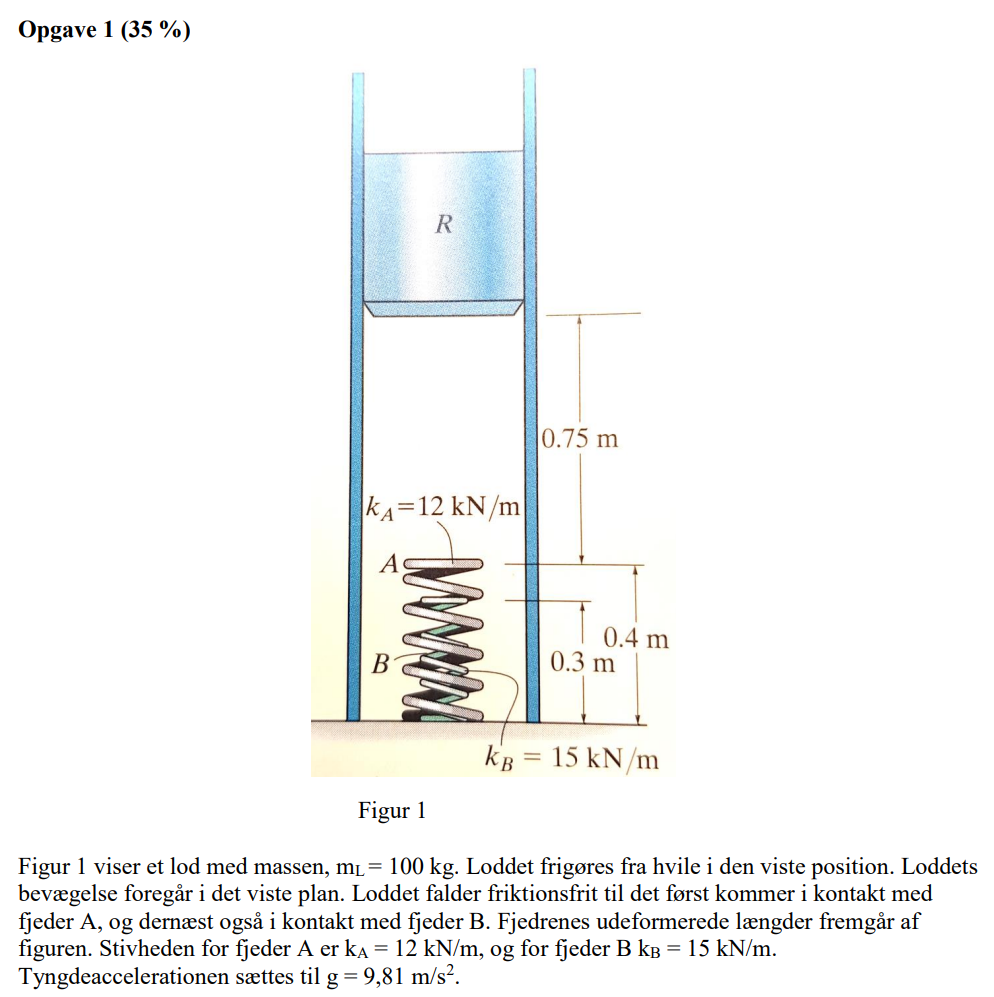

Fra opgave beskrivelsen er det oplyst:

- Loddets masse: 100 kg.

- Loddet frigøres fra hvile: $v_0 = 0$

- Der forekommer ingen friktion før loddet kommer i kontakt med fjeder A og B.

- Fjedernes uformerede længder er angivet som: $A = 0.4m \, \& \, B = 0.3m$

- Stivhed for fjeder A: $k_A = 12,000 \frac{N}{m}$

- Stivhed for fjeder B: $k_B = 15,000 \frac{N}{m}$

- Tyngdeaccelerationen: $g = 9.81 \frac{m}{s^2}$

- Loddet har en start position på 0.75 m.

s_0 = 0.75;
m = 100;
k_A = 12000;
k_B = 15000;
g = 9.81;
s_A = 0.4;
s_B = 0.3;

## A) Tiden fra loddet frigøres til det opnår kontakt med fjeder A

Ved brug af afstandsformlen kan vi finde frem til tiden det tager loddet at komme i kontakt med fjeder A:

- 
$$s = s_{0} + v_{0}*t+\frac{1}{2}*a*t^2$$


Hvoraf:

- 
$$s = 0.75$$


syms t;
s = s_0;
tiden = vpasolve(s == 0 + 0 + 0.5 * g * t^2,t)

$$tiden = \left(\begin{array}{c} -0.39103094350288751769324412040311\\ 0.39103094350288751769324412040311 \end{array}\right)$$

Hvoraf det tager loddet 0.286 sekunder at opnå kontakt med fjeder A.

## B) Loddets hastighed ved kontakt med fjeder A

Loddet hastighed kan findes ved hastighedsformlen:

- 
$$v = \frac{ds}{dt}=\dot{s} = v_0 + a * t \rightarrow v = -9.81\frac{m}{s^2} \cdot 0.286 s = -2.801 \frac{m}{s}$$


v = -g * tiden(2)

$$v = -3.8360135557633265485707248211545$$

## C) Loddets kinetiske energi, når loddet opnår kontakt med fjeder A

Loddets kinetiske energi er baseret på:

- 
$$T_1 + U_{1-2} = T_2$$


Da loddet er sluppet fra hvile, vil $T_1$ være ligmed nul.

Arbejdet, $U_{1-2}$, er angivet som:

- 
$$U_{1-2} =  \int_{x_1}^{x_2} P \cdot cos(\alpha) dx = P \cdot cos(\alpha) \cdot (x_2 - x_1) = P \cdot L \cdot cos(\alpha)$$


U_12 = m * -g * s

U_12 = -735.7500

Hvilket gør, at loddets kinetiske energi, når loddet opnår kontakt med fjeder A, er:

- 
$$T_1 + U_{1-2} = T_2 \rightarrow U_{1-2} = T_2 = 343.35 N\cdot m$$


## D) Loddets bevægelsesmængde (linear momentum) når loddet opnår kontakt med fjeder A

Loddets linear momentum kan bestemmes som:

- 
$$G = \Delta G 

\equiv 

G = m_2 \cdot v_2 - m_1 \cdot v_1 \rightarrow G = m_2 \cdot v_2 = 383.601$$


G = m * v

$$G = -383.60135557633265485707248211545$$

## E) Den maksimale sammentrykning af fjeder A, når loddet igen kommer i hvile

Den maksimale sammentrykning af fjeder A kan findes ved:

- 
$$-k + \delta_{st} + m \cdot g = 0$$


Hvoraf sammentrykningen bliver:

- 
$$\delta_{st} = \frac{100 kg \cdot 9.81 \cdot \frac{m}{s^2}}{27000 \frac{N}{m}} = 0.0818 m$$


delta = (m*g)/k_A

delta = 0.0818

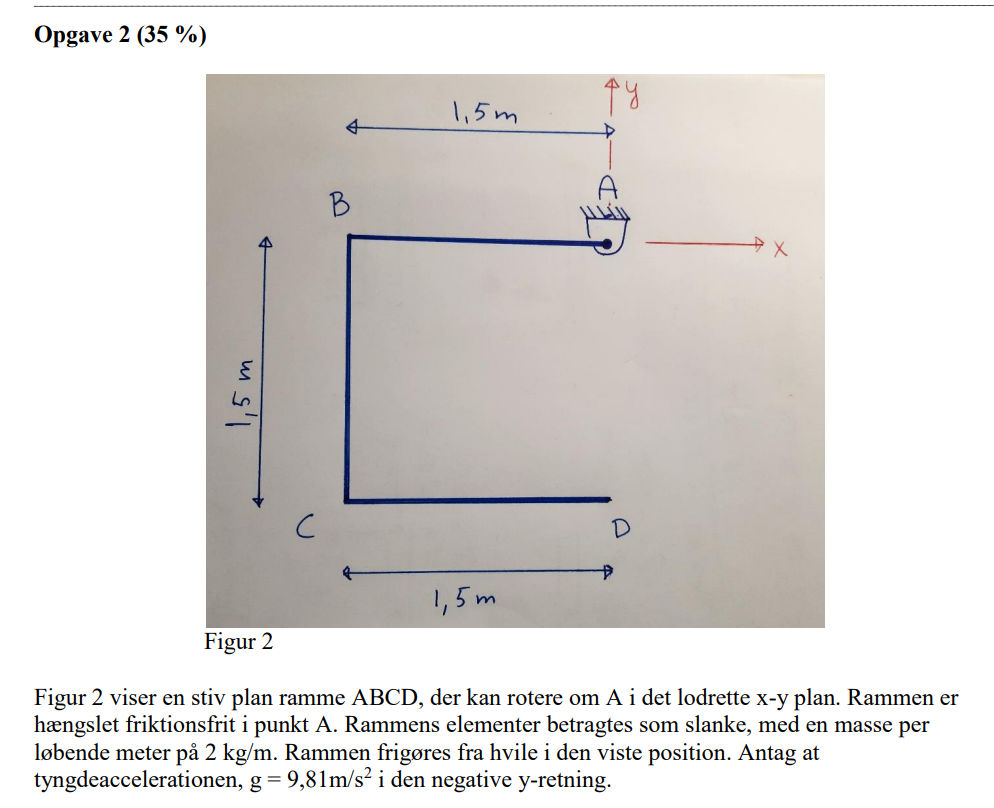

## A) Rammens masse

Oplyst fra opgaven er at rammen har en løbende masse per meter: $2 \frac{kg}{m}$

Rammen er $3 \cdot 1.5m = 4.5 m$

Hvilker gør at rammens masse er: $2 \frac{kg}{m} \cdot 4.5m = 9 kg$

## B) Tyngdepunktets position, samt en skitse som illustrerer tyngdepunktets placering

Tyngdepunktets position kan findes ved:

For x-retningen:

- 
$$\frac{\sum^{i}_{n = antal \, former} (m_i \cdot \overline x_i)}{\sum m} $$


For y-retningen:

- 
$$\frac{\sum^{i}_{n = antal \, former} (m_i \cdot \overline y_i)}{\sum m} $$


Formlen siger, at summen af hver forms masse gange formens tyngdepunkt divideredet med den samlede masse giver et henholdsvis x & y koordinat:

**For x koordinatet:**

- 
$$x = \frac{\sum^{i}_{n = antal \, former} (m_i \cdot \overline x_i)}{\sum m}  =

\frac{3kg \cdot 0.75m + 3kg \cdot 1.5m + 3kg \cdot 0.75m}{3\cdot 3 kg}

 = 1 m$$


x = (3 * 0.75 + 3 * 1.5 + 3 * 0.75)/(9)

x = 1

**For y koordinatet:**

- 
$$y = \frac{\sum^{i}_{n = antal \, former} (m_i \cdot \overline y_i)}{\sum m}  =

\frac{3kg \cdot 0 + 3kg \cdot 0.75 m + 3kg \cdot 1.5m}{3\cdot 3 kg}

 = 0.75m$$


y = (3 * 0 + 3 * 1.5 + 3 * 0.75)/(9)

y = 0.7500

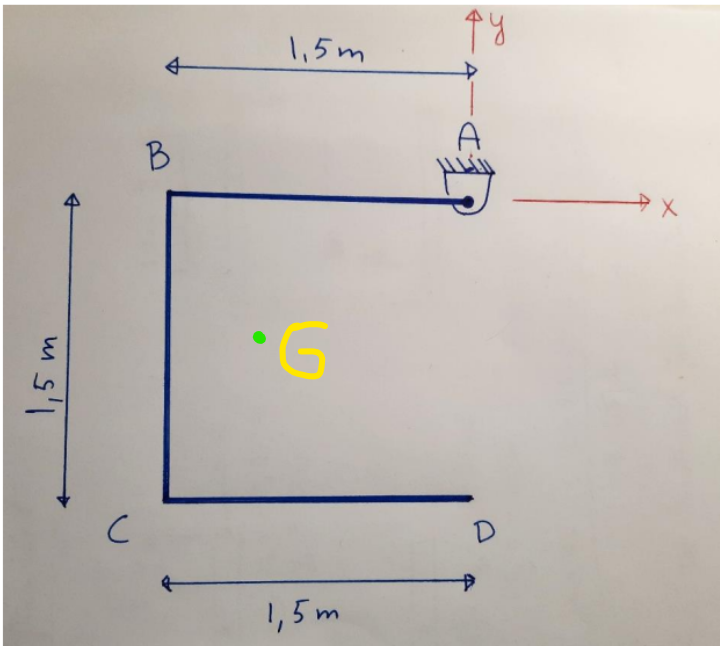

## C) Masseinertimomentet om A

Da vi har en ramme forbundet af tre slanker, så kan vi finde inertimomentet om A som:

Heraf kan vi finde $I_A$ som:

- 
$$I_A = I_G + m \cdot d^2$$


- 
$$I_A = I_{slanke_n} + m_{slanke_n} * d^2$$


Vi har tre slanker hvoraf...:

- 
$$I_A = I_{slanke_1} + m_{slanke_1} * d^2  + 
I_{slanke_2} + m_{slanke_2} * d^2  +
I_{slanke_3} + m_{slanke_3} * d^2 $$


Da den første af bjælkerne er forbundet til A, så skal der her ikke tilføjes m og distanse bidrag:

- 
$$I_A = I_{slanke_1}   + 
I_{slanke_2} + m_{slanke_2} * d^2  +
I_{slanke_3} + m_{slanke_3} * d^2  =  20.25 kg \cdot m^2$$


syms I_G;
I_1 = (1/3) * 3 * 1.5^2

I_1 = 2.2500

I_2 = (1/3) * 3 * 1.5^2 + 3 * 1.5^2

I_2 = 9

I_3 = (1/3) * 3 * 1.5^2 + 3 * 1.5^2

I_3 = 9

I_A = I_1 + I_2 + I_3

I_A = 20.2500

## D) Frit legeme diagram og kinetisk diagram

Gjort. Se side 212 / 196 (i bogen) for inspiration til FDB og KD.

## E) Vinkelaccelerationen

Vinkelaccelerationen kan findes gennem formlen:

- 
$$\sum M_A = I_A \cdot \alpha$$


Heraf vil momentet dannes af rammens egenvægt og armen fra tyngdepunktet til omdrejningspunktet:

- 
$$m \cdot g \cdot x = I_A \cdot \alpha \rightarrow \alpha = \frac{m \cdot g \cdot x}{I_A} = 4.36 \frac{rads}{s^2}$$


alpha = (9 * 9.81 * 1)/I_A

alpha = 4.3600

## F) Tyngdepunktets acceleration i x- og y-retningerne, samt en skitse som illustrerer de to accelerationer

Accelerationen i x og y retningen er angivet på baggrund af vores valgte koordinat system:

- 
$$n - t -koordinatsystem$$


Hertil skal vi kende vinklen samt afstanden der dannes mellem tyngdepunktet og A. 

- 
$$\theta = atan(\frac{\overline y_G}{\overline x_G}) = 
36.8699\degree $$


- 
$$d = r_G = \sqrt{x_G^2 + y_G^2} \rightarrow d = \sqrt{(-1)^2 + (-0.75)^2} = 1.25m$$


theta = atand(-0.75/-1)

theta = 36.8699

d = sqrt(1^2 + 0.75^2)

d = 1.2500

Med afstandene og vinklen kendt, så kan vi diffinere den tangielle acceleration: $a_t$

- 
$$a_t = d \cdot \alpha = 5.45 \frac{rads}{s^2}$$


a_t = d * alpha

a_t = 5.4500

Heraf er $a_{y_G} \, \& \, a_{x_G}$ angivet som:

- 
$$a_{y_G} = a_t \cdot cos(\theta) = 3.6812 \frac{rads}{s^2}$$


-  
$$a_{x_G} = a_t \cdot sin(\theta) = -4.0188 \frac{rads}{s^2}$$


a_yG = a_t * cos(theta)

a_yG = 3.6812

a_xG = a_t * sin(theta)

a_xG = -4.0188

## G) Reaktionerne Ax og Ay 

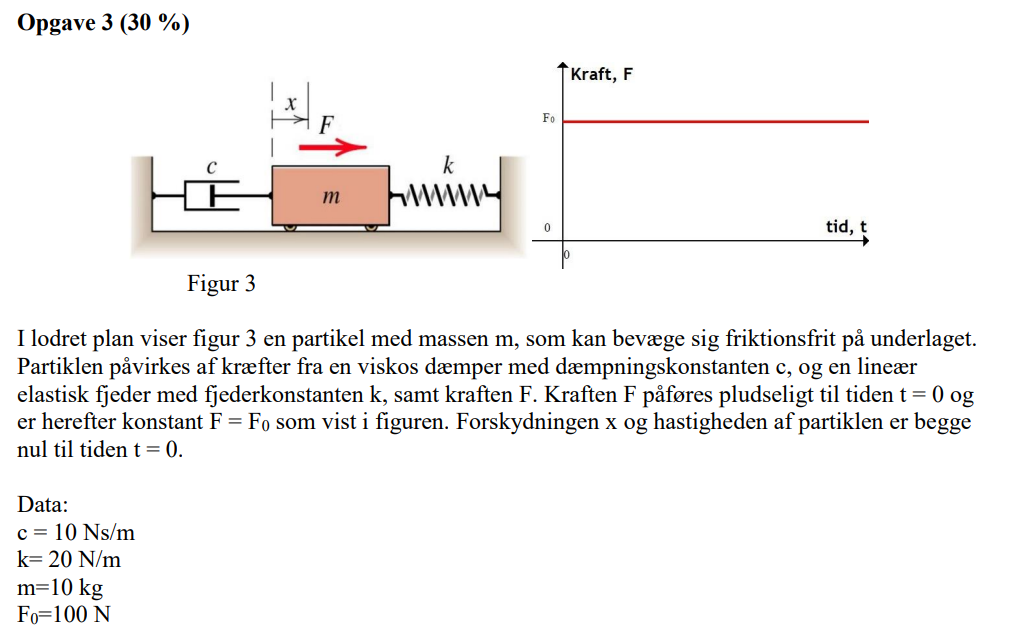

## A) Den normerede bevægelsesligning, ligningen ønskes opskrevet symbolsk

Før dæmpningsforholdet er beskrevet er det uvidst om en anden bevægelsesligning kan anvendes, hvoraf standard lingingen for bevægelse er angivet som:

- 
$$\ddot x + 2 \cdot \zeta \cdot \omega_n \cdot \dot x + \omega_n^2 \cdot x = \frac{F_0 \cdot sin(\omega \cdot t}{m}$$


## B) Egenfrekvensen $\omega_n$

Egenfrekvensen er angivet som:

- 
$$\omega_n = \sqrt{\frac{k}{m}} = 1.4142 \frac{rads}{s}$$


c = 10;
k = 20;
m = 10;
F_0 = 100;
omega_n = sqrt(k/m)

omega_n = 1.4142

## C) Dæmpningsforholdet $\zeta$ og afgør typen af dæmpning (overdæmpet, kritisk dæmpet eller  underdæmpet)

Dæmpningsforholdet, zeta, er angivet som:

- 
$$\zeta = \frac{c}{2 \cdot m \cdot \omega_n} = 0.3536$$


Hvoraf systemet er underdæmpet.

zeta = c/(2*m*omega_n)

zeta = 0.3536

## D) Den dæmpede egenfrekvens $\omega_d$

Den dæmpede egenfrekvens er angivet som:

- 
$$\omega_d = \omega_n \cdot \sqrt{1- \zeta^2} = 1.3229$$


omega_d = omega_n * sqrt(1-zeta^2)

omega_d = 1.3229

## E) Vis at $x_p(t) = \frac{F_0}{k}$ er en partikulær løsning til bevægelsesligningen.


$$\ddot x + 2\zeta\omega_n\dot x + \omega_n^2x = \frac{F_0}{m}$$



$$x(t) = \frac{F_0}{k} \\
x'(t) = 0 \\
x''(t) = 0$$


vi får nu


$$\omega_n^2 \frac{F_0}{k} = \frac{F_0}{m} \\
\omega_n^2 = \frac{k}{m} \\
\frac{F_0}{m} = \frac{F_0}{m} $$


## F) Forskydningen $x(t)$

Ved anvendelse af sætning 8/11 får vi en bevægelsesligning:

- 
$$x(t) = (A \cdot cos(\omega_d \cdot t ) + B \cdot sin(\omega_d \cdot t)) \cdot e^{-\zeta \cdot \omega_n \cdot t}$$


Ved partielt differentiale til t kan vi få hastighedsligningen, hvorfra vi kan bestemme konstanterne A & B:

- 
$$\dot x(t) = (B \cdot \omega_d \cdot cos(\omega_d \cdot t) - A \cdot \omega_d \cdot sin(\omega_d \cdot t)) \cdot e^{-\omega_n \cdot \zeta \cdot t} -\omega_n \cdot \zeta \cdot e^{-\omega_n \cdot \zeta \cdot t} \cdot (A \cdot cos(\omega_d \cdot t) + B \cdot sin(\omega_d \cdot t))$$


syms A B t x dx
eq1 = (A * cos(omega_d * t) + B * sin(omega_d * t)) * exp(-zeta * omega_n * t) == x

$$eq1 = {\mathrm{e}}^{-\frac{t}{2}}\,\left(A\,\cos\left(\frac{\sqrt{7}\,t}{2}\right)+B\,\sin\left(\frac{\sqrt{7}\,t}{2}\right)\right)=x$$


eq2 = (B * omega_d * cos(omega_d * t) - A * omega_d * sin(omega_d * t)) * exp(-omega_n *zeta * t) * (A * cos(omega_d * t) + B *sin(omega_d *t)) == dx

$$eq2 = {\mathrm{e}}^{-\frac{t}{2}}\,\left(\frac{\sqrt{7}\,B\,\cos\left(\frac{\sqrt{7}\,t}{2}\right)}{2}-\frac{\sqrt{7}\,A\,\sin\left(\frac{\sqrt{7}\,t}{2}\right)}{2}\right)\,\left(A\,\cos\left(\frac{\sqrt{7}\,t}{2}\right)+B\,\sin\left(\frac{\sqrt{7}\,t}{2}\right)\right)=\mathrm{dx}$$


eq3 = solve([eq1 eq2], [A B]);
eq3.A

$$ans = \frac{7\,x^{2}\,{\mathrm{e}}^{t/2}\,\cos\left(\frac{\sqrt{7}\,t}{2}\right)-2\,\sqrt{7}\,\mathrm{dx}\,\sin\left(\frac{\sqrt{7}\,t}{2}\right)}{7\,x\,{\cos\left(\frac{\sqrt{7}\,t}{2}\right)}^{2}+7\,x\,{\sin\left(\frac{\sqrt{7}\,t}{2}\right)}^{2}}$$

eq3.B

$$ans = \frac{7\,{\mathrm{e}}^{t/2}\,\sin\left(\frac{\sqrt{7}\,t}{2}\right)\,x^{2}+2\,\sqrt{7}\,\mathrm{dx}\,\cos\left(\frac{\sqrt{7}\,t}{2}\right)}{7\,x\,{\cos\left(\frac{\sqrt{7}\,t}{2}\right)}^{2}+7\,x\,{\sin\left(\frac{\sqrt{7}\,t}{2}\right)}^{2}}$$

## G) Plot forskydningen x(t) for 0 ≤ t ≤ 10 s. I samme plot ønskes den statiske forskydning F0/k indtegnet